close all; clear all; clc;clear vars;
%====================User Input================================
% Define the initial value of load/displacement 
% LOAD.amp = [0.012 0.024 0.036 0.048 0.06];  %custom peak amplitude of each cycle
for i = 1:3
    LOAD.amp(i) = 0.012*i;
end
LOAD.node = [5 7];       %Node in which the disp is applied
step = 3

step = 3

%====================End of User Input=========================

U = [0];
input_array = [];
for q = 1:length(LOAD.amp);   
    
    temp_cycle = [];
    % Define the initial value of y and the total number of steps
    DISPLACEMENT = LOAD.amp(q);
    % Initialize temporary u for each amplitude cycle
    u = zeros(1, length(step*2));

        %increment to the target displacement amplitude
        increment = DISPLACEMENT / step;
        for i = 1:step
            u(i) = increment*(i);
            temp_cycle = [temp_cycle increment];
        end
        
        %decrement to the target displacement amplitude
        unload = u(i)/step;
        for i = i+1:step*2
            u(i) = u(i-1) - unload;
            temp_cycle = [temp_cycle -unload];
        end
        U = [ U [u(:)]' [-1.*u(:)]'];
        
        input_array = [input_array temp_cycle -temp_cycle];
    
end

%This will be the increment of disp that will be applied in every step
input_array

input_array =     0.0040    0.0040    0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040   -0.0040    0.0040    0.0040    0.0040    0.0080    0.0080    0.0080   -0.0080   -0.0080   -0.0080   -0.0080   -0.0080   -0.0080    0.0080    0.0080    0.0080    0.0120    0.0120    0.0120   -0.0120   -0.0120   -0.0120   -0.0120   -0.0120   -0.0120    0.0120    0.0120    0.0120


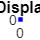


X = 0:length(U)-1;

% Plot the graph
figure();
plot(X, U, 'b.-');
xlabel('Step');
ylabel('Displacement');
title('Cyclic Displacement');


csvwrite('u_input.csv',input_array);



